% % MILP problem to risk appetite model
clc
clear all

% % Loading data set
IS = xlsread("Utility_estimation.xlsx",'IS_PA'); % Information System from respondent evaluations
Data_based_case = xlsread('Utility_estimation.xlsx','DT_PA'); % Utility estimation from RSGA


% % Define the features
U = Data_based_case(:,1); % Number of observation
Utility_R = round(Data_based_case(:,1:end-1)); % Number of utility estimation

Cond_R = IS(:,1:end-1); % Number of conditional seaport risk factors

Dec_R = Data_based_case(:,end); % Decisional seaport risk factor


% % Formulating the problem
utilityprob = optimproblem("ObjectiveSense","minimize")

utilityprob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [0×0 struct] containing 0 OptimizationVariables
         Objective: [0×0 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  No problem defined.


e = optimvar('e',83,61,'Type','integer','LowerBound',0,'UpperBound',1);
show(e)

    [ e(1, 1)     e(1, 2)     e(1, 3)     e(1, 4)     e(1, 5)     e(1, 6)     e(1, 7)     e(1, 8)     e(1, 9)     e(1, 10)     e(1, 11)     e(1, 12)     e(1, 13)     e(1, 14)     e(1, 15)     e(1, 16)     e(1, 17)     e(1, 18)     e(1, 19)     e(1, 20)     e(1, 21)     e(1, 22)     e(1, 23)     e(1, 24)     e(1, 25)     e(1, 26)     e(1, 27)     e(1, 28)     e(1, 29)     e(1, 30)     e(1, 31)     e(1, 32)     e(1, 33)     e(1, 34)     e(1, 35)     e(1, 36)     e(1, 37)     e(1, 38)     e(1, 39)     e(1, 40)     e(1, 41)     e(1, 42)     e(1, 43)     e(1, 44)     e(1, 45)     e(1, 46)     e(1, 47)     e(1, 48)     e(1, 49)     e(1, 50)     e(1, 51)     e(1, 52)     e(1, 53)     e(1, 54)     e(1, 55)     e(1, 56)     e(1, 57)     e(1, 58)     e(1, 59)     e(1, 60)     e(1, 61)  ]
    [ e(2, 1)     e(2, 2)     e(2, 3)     e(2, 4)     e(2, 5)     e(2, 6)     e(2, 7)     e(2, 8)     e(2, 9)     e(2, 10)     e(2, 11)     e(2, 12)     e(2, 13)     e(2, 14)     e(2, 15)     e(2, 16)     e(2, 1


utilityEstimation = Utility_R;
riskPreferences = Cond_R;
Decisional_SR = Dec_R;
Percentage_utility = Utility_R.*Decisional_SR

Percentage_utility =            6           0          -8           2         -10           0           8         -14          14          -4           6          -4          -8         -10          12           8         -90         -86          52          54          80          98         -72         -78          44          12          12           4         -34          -4          12         -14           8           4           0         -28          -4          28         -48         -56         -34         116          58         -36         102         -48         -54         -30          14          16
          39          24         -28          74         -42         -11         -10         -24         -21        -108        -104          -1           0           2         119          93         -55         -55         -55          43         129          53          50         -55         -55          28         -47        -150         151          22         -45      

Freq_entities = length(Utility_R)/3

Freq_entities = 27.6667

F = 1./Freq_entities

F = 0.0361


if max(utilityEstimation(:))
    predprob = 1
else
    predprob = 0
end

predprob = 1


% % Creating expressions
Z = F.*sum(sum(Cond_R.*predprob.*utilityEstimation.*e))

Z =   Linear OptimizationExpression

    0.216867*e(1, 1) + 7.04819*e(2, 1) - 2.16867*e(3, 1) + 3.25301*e(4, 1) + 0.759036*e(5, 1) + 1.15663*e(6, 1) - 3.18072*e(7, 1) - 0.144578*e(8, 1) - 0.289157*e(9, 1) - 2.63855*e(10, 1) + 3.54217*e(11, 1) + 3.36145*e(12, 1) - 0.216867*e(13, 1) - 1.73494*e(14, 1) - 0.722892*e(15, 1) + 1.59036*e(16, 1) - 4.62651*e(17, 1) + 0.506024*e(18, 1) - 2.89157*e(19, 1) - 2.24096*e(20, 1) - 2.31325*e(21, 1) - 0.939759*e(22, 1) - 1.66265*e(23, 1) + 6.07229*e(24, 1) - 0.795181*e(25, 1) + 6.83133*e(26, 1) + 2.45783*e(27, 1) - 3.03614*e(28, 1) + 0.144578*e(29, 1) - 3*e(30, 1) - 5.16867*e(31, 1) + 0.506024*e(32, 1) + 2.74699*e(33, 1) + 1.08434*e(34, 1) - 0.289157*e(35, 1) + 10.8434*e(36, 1) - 5.31325*e(37, 1) - 0.86747*e(38, 1) - 3.54217*e(39, 1) - 2.96386*e(40, 1) - 6*e(41, 1) - 0.939759*e(42, 1) - 0.650602*e(43, 1) - 4.12048*e(44, 1) - 0.253012*e(45, 1) + 0.144578*e(46,

utilityprob.Objective = Z; % Objective function
show(Z)


  0.216867*e(1, 1) + 7.04819*e(2, 1)
- 2.16867*e(3, 1) + 3.25301*e(4, 1)
+ 0.759036*e(5, 1) + 1.15663*e(6, 1)
- 3.18072*e(7, 1) - 0.144578*e(8, 1)
- 0.289157*e(9, 1) - 2.63855*e(10, 1)
+ 3.54217*e(11, 1) + 3.36145*e(12, 1)
- 0.216867*e(13, 1) - 1.73494*e(14, 1)
- 0.722892*e(15, 1) + 1.59036*e(16, 1)
- 4.62651*e(17, 1) + 0.506024*e(18, 1)
- 2.89157*e(19, 1) - 2.24096*e(20, 1)
- 2.31325*e(21, 1) - 0.939759*e(22, 1)
- 1.66265*e(23, 1) + 6.07229*e(24, 1)
- 0.795181*e(25, 1) + 6.83133*e(26, 1)
+ 2.45783*e(27, 1) - 3.03614*e(28, 1)
+ 0.144578*e(29, 1) - 3*e(30, 1) - 5.16867*e(31, 1)
+ 0.506024*e(32, 1) + 2.74699*e(33, 1)
+ 1.08434*e(34, 1) - 0.289157*e(35, 1)
+ 10.8434*e(36, 1) - 5.31325*e(37, 1)
- 0.86747*e(38, 1) - 3.54217*e(39, 1)
- 2.96386*e(40, 1) - 6*e(41, 1) - 0.939759*e(42, 1)
- 0.650602*e(43, 1) - 4.12048*e(44, 1)
- 0.253012*e(45, 1) + 0.144578*e(46, 1)
+ 0.144578*e(47, 1) - 1.01205*e(48, 1)
- 1.15663*e(49, 1) + 0.361446*e(51, 1)
- 0.506024*e(52, 1) + 0.939759*e(53, 1)
+ 7.04819*e(

% % Defining constaints
for m = 1:83
    for n = 1:61
        if utilityEstimation(m,n) ~= utilityEstimation(n)
            d_ikj(m,n) = 1;
        else
            d_ikj(m,n) = 0;
        end
    end
end

d_ikj_cons1 = sum(d_ikj.*e) <= 1

d_ikj_cons1 =   1×61 Linear OptimizationInequality array with properties:

    IndexNames: {{}  {}}
     Variables: [1×1 struct] containing 1 OptimizationVariable

  See inequality formulation with show.


utilityprob.Constraints.d_ikj_cons1 = d_ikj_cons1

utilityprob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 1 OptimizationConstraint

  See problem formulation with show.


% % Solve the problem
[sol, fval] = solve(utilityprob)

Solving problem using intlinprog.
LP:                Optimal objective value is -867.108434.                                          


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the
optimal value, options.AbsoluteGapTolerance = 0 (the
default value). The intcon variables are
integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



sol = struct with fields:
    e: [83×61 double]


fval = -867.1084

sol.e

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

fval

fval = -867.1084

% % Plotting result
h = heatmap(sol.e)

h =   HeatmapChart with properties:

        XData: {61×1 cell}
        YData: {83×1 cell}
    ColorData: [83×61 double]

  Show all properties


h.Title = 'Risk appetite of Port Autorithy (Seaport-maneger and Seaport-operator) under Scenario I'

h =   HeatmapChart (Risk appetite of Port Autorithy (Seaport-maneger and Seaport-operator) under Scenario I) with properties:

        XData: {61×1 cell}
        YData: {83×1 cell}
    ColorData: [83×61 double]

  Show all properties


h.XLabel = 'Conditional seaport risk factors'

h =   HeatmapChart (Risk appetite of Port Autorithy (Seaport-maneger and Seaport-operator) under Scenario I) with properties:

        XData: {61×1 cell}
        YData: {83×1 cell}
    ColorData: [83×61 double]

  Show all properties


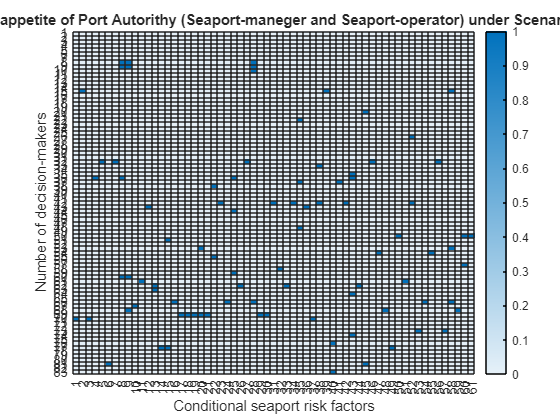

h =   HeatmapChart (Risk appetite of Port Autorithy (Seaport-maneger and Seaport-operator) under Scenario I) with properties:

        XData: {61×1 cell}
        YData: {83×1 cell}
    ColorData: [83×61 double]

  Show all properties


h.YLabel = 'Number of decision-makers'


s = surf(sol.e)

s =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [83×1 double]
           ZData: [83×61 double]
           CData: [83×61 double]

  Show all properties


s.EdgeColor = "interp"

s =   Surface with properties:

       EdgeColor: 'interp'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [83×1 double]
           ZData: [83×61 double]
           CData: [83×61 double]

  Show all properties


s.FaceColor = "interp"

s =   Surface with properties:

       EdgeColor: 'interp'
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [83×1 double]
           ZData: [83×61 double]
           CData: [83×61 double]

  Show all properties


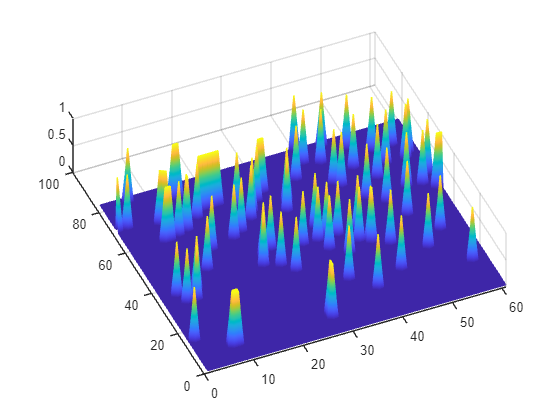


view([-23.400 76.200])